**EX-3:The Beverage-Can Problem. The standard beverage can holds 12 fl. oz, or has a volume of 21.66  What dimensions yield the minimum surface area? Find the minimum surface area. (Assume that the shape of the can is a right circular cylinder**

 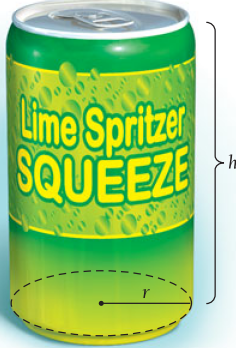

clear variables 
syms r h positive 
syms lambda 
f=2*pi*r*h+2*pi*r^2

$$f = 2\,\pi \,r^{2}+2\,h\,\pi \,r$$

g=pi*r^2*h-21.66

$$g = \pi \,h\,r^{2}-\frac{1083}{50}$$

F=f+ lambda*g

$$F = \lambda \,\left(\pi \,h\,r^{2}-\frac{1083}{50}\right)+2\,\pi \,r^{2}+2\,\pi \,h\,r$$

Fr=diff(F,r)

$$Fr = 2\,\pi \,h+4\,\pi \,r+2\,\pi \,h\,\lambda \,r$$

Fh=diff(F,h)

$$Fh = \lambda \,\pi \,r^{2}+2\,\pi \,r$$

L1=solve(Fr,lambda)

$$L1 = -\frac{h+2\,r}{h\,r}$$

L2=solve(Fh,lambda)

$$L2 = -\frac{2}{r}$$

eqns= [L1==L2]

$$eqns = -\frac{h+2\,r}{h\,r}=-\frac{2}{r}$$

solh=solve(eqns,h)

$$solh = 2\,r$$

g1=subs(g,{h},{solh})

$$g1 = 2\,\pi \,r^{3}-\frac{1083}{50}$$

r1=double(solve(g1))

r1 = 1.5106

h1=double(subs(solh,{r},{r1}))

h1 = 3.0213

min_sa=double (subs(f,{r,h},{r1,h1}))

min_sa = 43.0150

## Ex-4: Minimizing construction costs. A company is planning

## to construct a warehouse whose interior volume is to be

## 252,000  Construction costs per square foot are estimated to be as follows:

Walls: $3.00

Floor: $4.00

Ceiling: $3.00

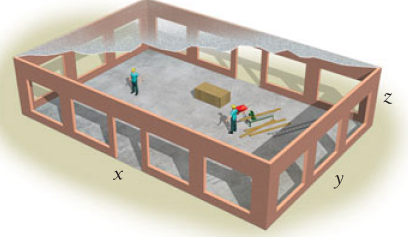

syms x y z lambda
f=7*x*y+6*y*z+6*x*z  %  surface area of the box 

$$f = 7\,x\,y+6\,x\,z+6\,y\,z$$

g=x*y*z-252000   % constraint: Volume of the box

$$g = x\,y\,z-252000$$

ae=f+lambda*g            % auxillary equation

$$ae = 7\,x\,y+6\,x\,z+6\,y\,z+\lambda \,\left(x\,y\,z-252000\right)$$

dae_x=diff(ae,x)

$$dae\_x = 7\,y+6\,z+\lambda \,y\,z$$

dae_y=diff(ae,y)

$$dae\_y = 7\,x+6\,z+\lambda \,x\,z$$

dae_z=diff(ae,z)

$$dae\_z = 6\,x+6\,y+\lambda \,x\,y$$

L1=solve(dae_x,lambda)

$$L1 = -\frac{7\,y+6\,z}{y\,z}$$

L2=solve(dae_y,lambda)

$$L2 = -\frac{7\,x+6\,z}{x\,z}$$

L3=solve(dae_z,lambda)

$$L3 = -\frac{6\,x+6\,y}{x\,y}$$

eqns = [L1-L2 == 0, L1-L3 == 0];
%vars = [x y];
[solx, soly] = solve(eqns, x,y)

$$solx = \frac{6\,z}{7}$$

$$soly = \frac{6\,z}{7}$$

g1=subs(g,{x,y},{solx,soly})

$$g1 = \frac{36\,z^{3}}{49}-252000$$

z1=solve(g1,z>0)          %  z=z1

$$z1 = 70$$

x1=subs(solx,{z},{z1})    %  x=x1

$$x1 = 60$$

y1=subs(soly,{z},{z1})    %  y=y1

$$y1 = 60$$

fprintf(" The dimensions of the rectangualr box are\n")

 The dimensions of the rectangualr box are


fprintf(" Length = %.2f, Width = %.2f and Height = %.2f\n",x1,y1,z1)

 Length = 60.00, Width = 60.00 and Height = 70.00
